per = 20

threshold_dist_1 = 0.3029

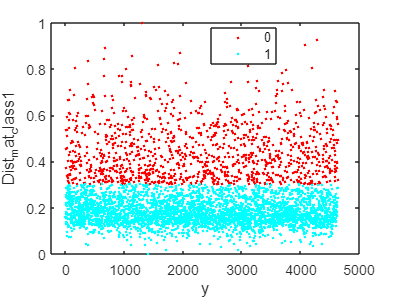

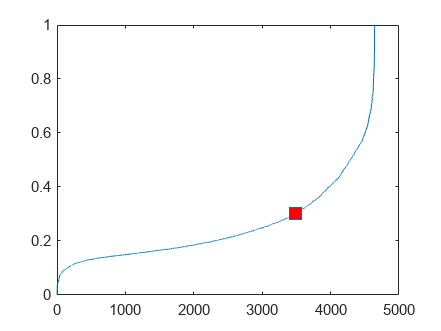

r1 = 1157

threshold_dist_7 = 0.9478

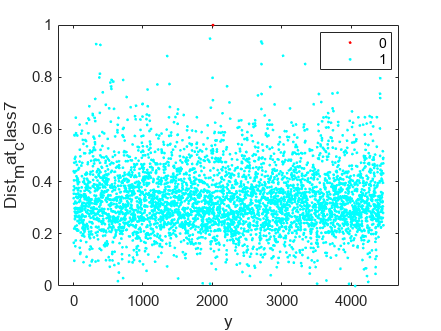

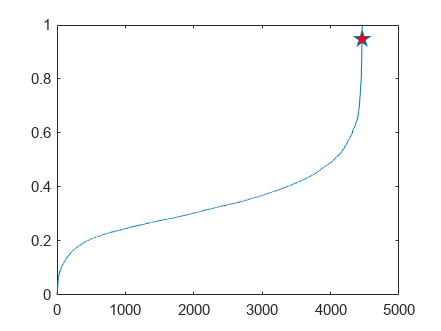

r7 = 1

per = 20

threshold_dist_1 = 0.2745

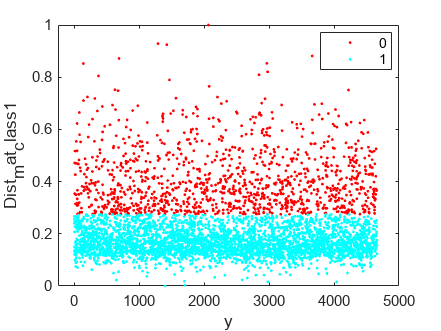

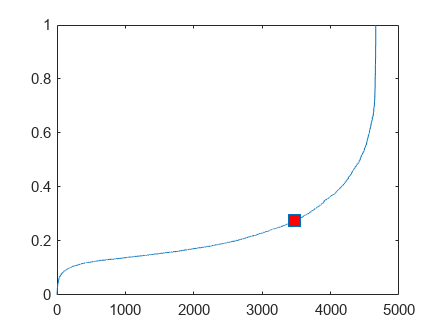

r1 = 1194

threshold_dist_7 = 0.9393

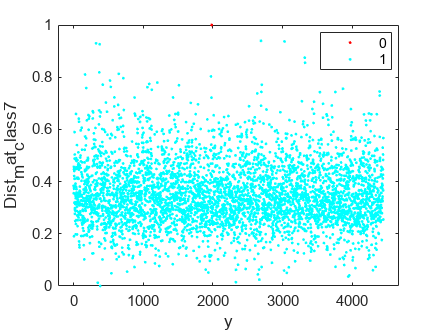

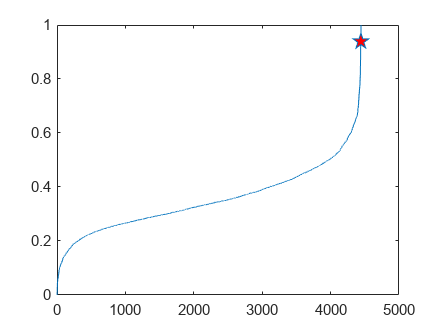

r7 = 1

per = 20

threshold_dist_1 = 0.2819

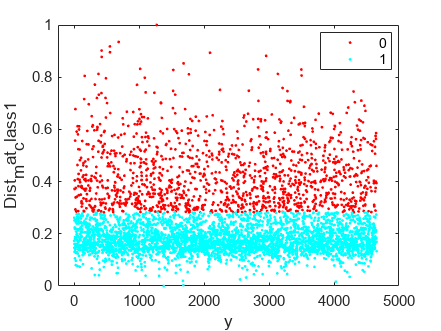

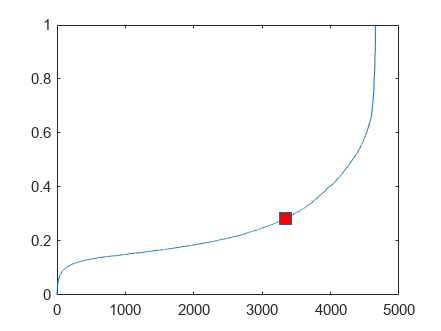

r1 = 1320

threshold_dist_7 = 0.9517

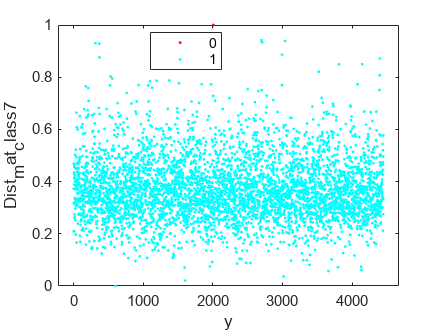

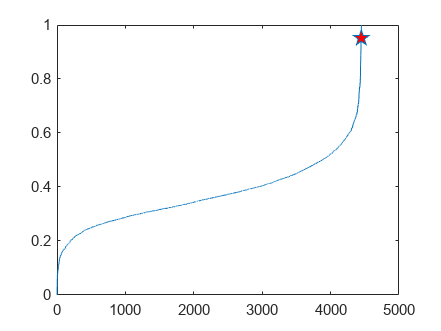

r7 = 1

per = 20

threshold_dist_1 = 0.2975

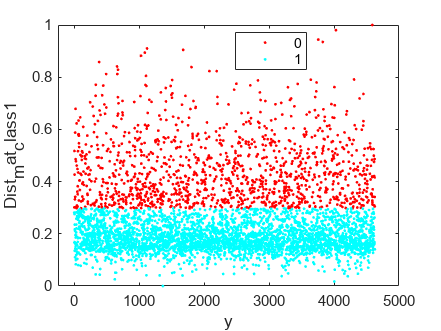

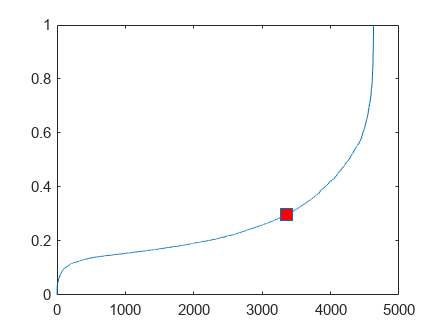

r1 = 1267

threshold_dist_7 = 0.9927

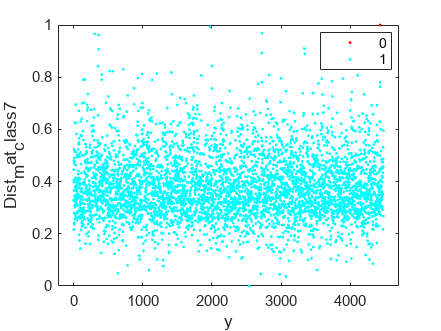

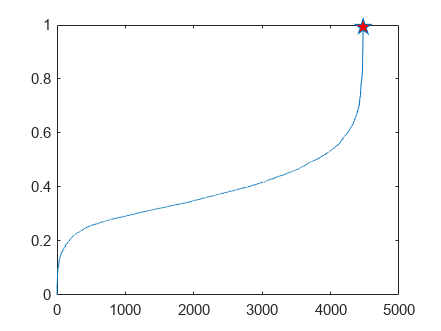

r7 = 1

per = 20

threshold_dist_1 = 0.2724

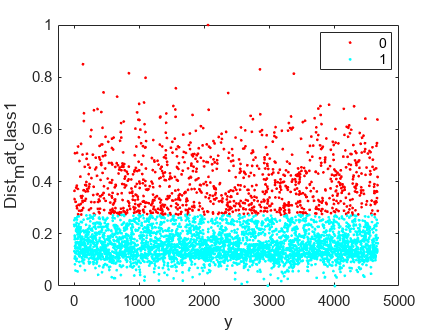

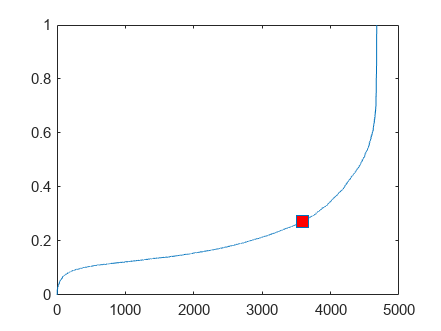

r1 = 1084

threshold_dist_7 = 0.9563

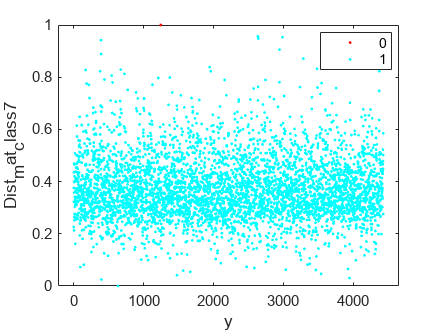

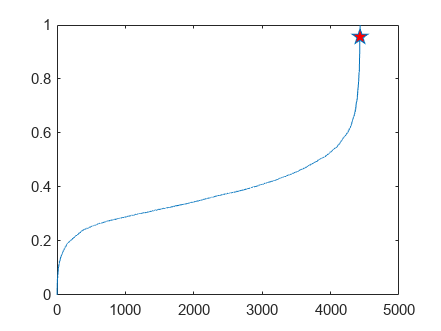

r7 = 1

per = 20

threshold_dist_1 = 0.3116

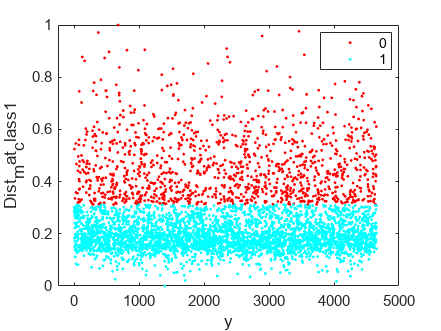

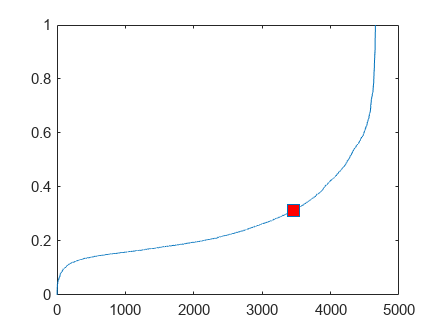

r1 = 1201

threshold_dist_7 = 0.9798

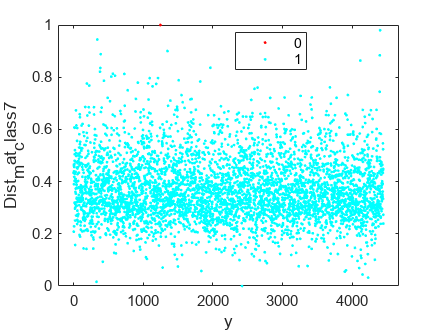

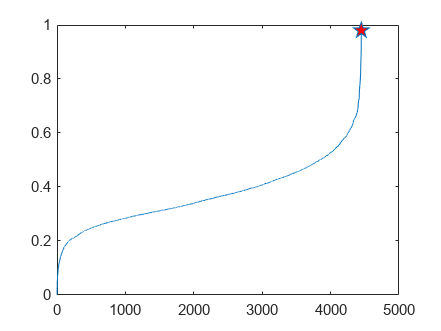

r7 = 1

per = 20

threshold_dist_1 = 0.2721

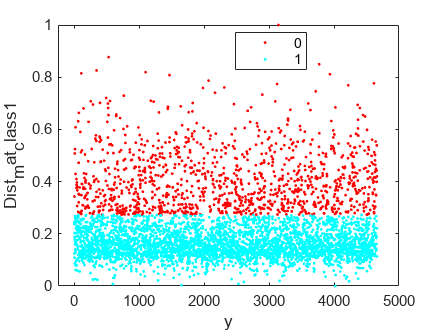

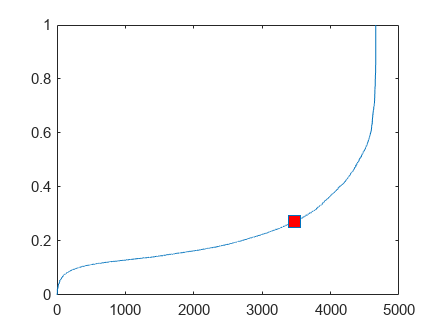

r1 = 1183

threshold_dist_7 = 0.9607

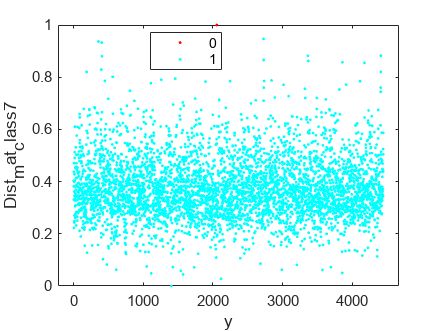

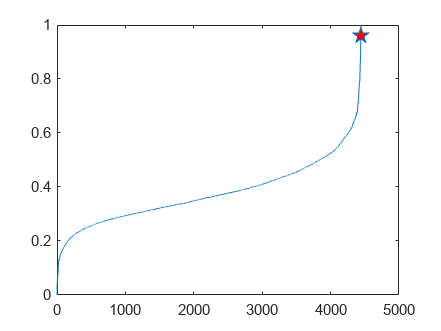

r7 = 1

per = 20

threshold_dist_1 = 0.3360

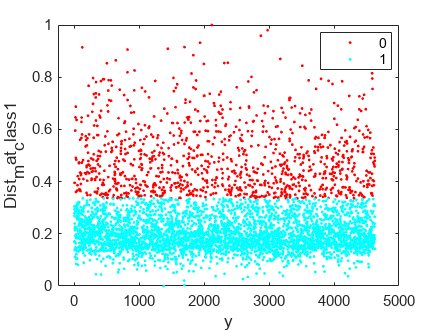

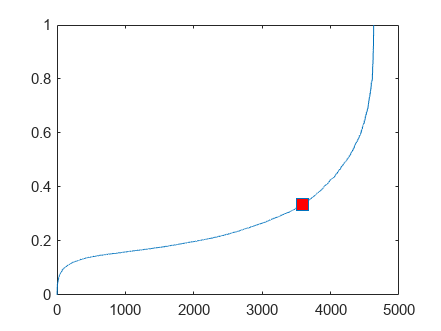

r1 = 1040

threshold_dist_7 = 0.9901

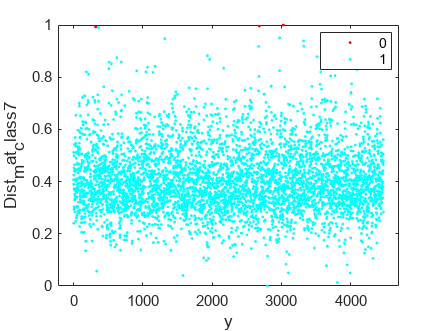

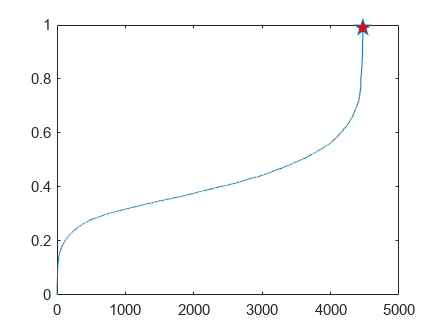

r7 = 3

per = 20

threshold_dist_1 = 0.3127

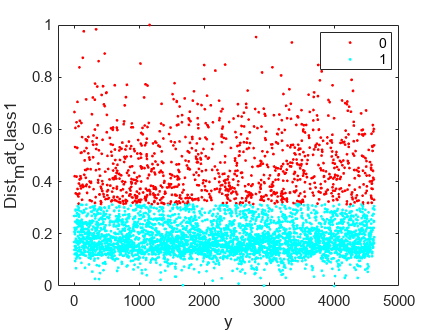

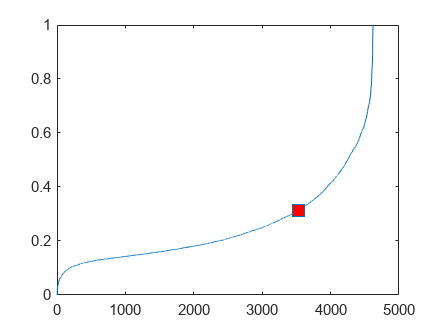

r1 = 1091

threshold_dist_7 = 0.9664

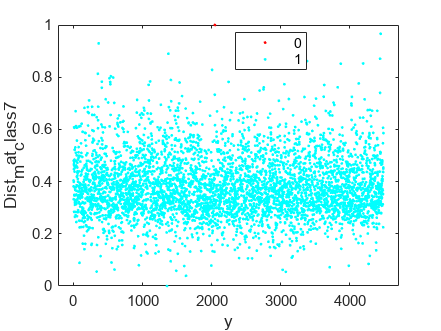

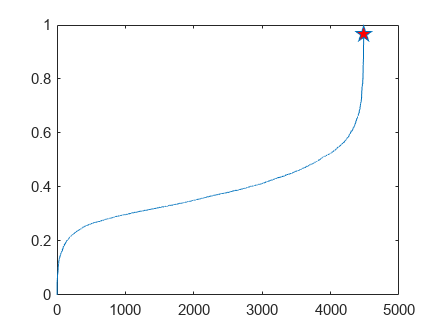

r7 = 1

per = 20

threshold_dist_1 = 0.3260

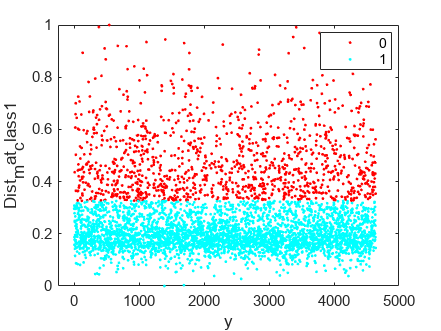

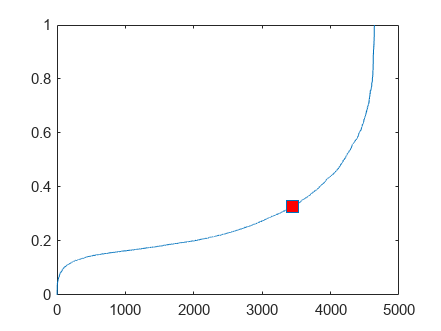

r1 = 1203

threshold_dist_7 = 0.9567

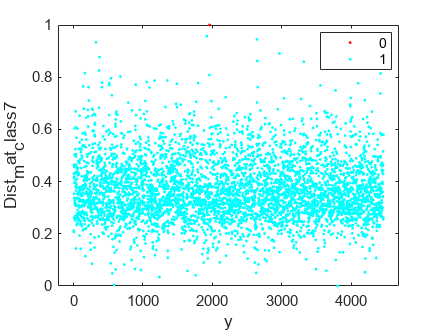

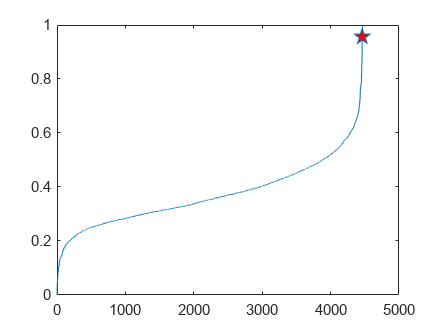

r7 = 1

for j = [1,2,3,4,5,6,7,8,9,10]
    splitfolder=strcat('split',num2str(j));
    M=importdata("C:\Users\shukl\Documents\GitHub\Mnist\split1\per20\mnist_misclass_per_20.csv",",",1);
    per =20%,10,5,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\Mnist\
        mkdir (splitfolder)
        cd (splitfolder)
        folder=strcat('per',num2str(percent));
        %         mkdir (folder)
        cd (folder)


        my_file = strcat('mnist_17_misclass_per_',num2str(percent),'.csv');
        File=readmatrix(my_file,"NumHeaderLines",1);

        class1=File(File(:,1)==1,2:785);
        T_class1=class1.';
        T_class1_org=class1.';
        ind_one=find(File(:,1)==1);
        F_class1=[ind_one class1];

        class7=File(File(:,1)==7,2:785);
        T_class7=class7.';
        T_class7_org=class7.';
        ind_seven=find(File(:,1)==7);
        F_class7=[ind_seven class7];
        folder_l1=strcat('ACE_17_dist_knee_l1pca_per',num2str(percent));
        mkdir (folder_l1)

       

        i=1;

        cd C:\Users\shukl\Documents\GitHub\Mnist\

        Dist_mat_class1=[];


        numclass1=length(T_class1);

        T_class1;
        BF_class1=l1pca_BF(T_class1,i,1,100,100,'');
        for k = 1 : numclass1

            A=T_class1(:,k);
            Dist_mat_class1(k)=norm((A-(BF_class1*BF_class1.'*A)),1);
            k;

        end
        Dist_mat_class1;
        min_val=min(Dist_mat_class1,[],"all");
        max_val=max(Dist_mat_class1,[],"all");
        Dist_mat_class1= Dist_mat_class1 -min_val;%]/[max_val-min_val]
        Dist_mat_class1=Dist_mat_class1 /(max_val-min_val);


        Dist_mat_class1;

        [Dist_mat_class1_asc,Indx_1]=sort(Dist_mat_class1,"ascend");

        y_1=Dist_mat_class1_asc;
        
        [elbow_1,elbow_indx_1]=knee_pt(y_1);


        threshold_dist_1= Dist_mat_class1_asc(elbow_indx_1)
    

        ind_O_1=find(Dist_mat_class1>threshold_dist_1);
        ind_I_1=find(Dist_mat_class1<=threshold_dist_1);


        
        cluster_1=zeros(size(Dist_mat_class1));
        cluster_1(ind_I_1)=1;
        figure
        y= 1:1:length(class1);
        numGroups = length(unique(cluster_1));
        gscatter(y,Dist_mat_class1,cluster_1,hsv(numGroups))

        figure
        plot(Dist_mat_class1_asc,'-s',"MarkerIndices",(elbow_indx_1),'MarkerFaceColor','red','MarkerSize',10 )

        r1=length(ind_O_1)
        
        T_class1(:,ind_O_1)=[];



        Final_class1=T_class1';

        c1=ones(size(Final_class1,1),1);
        Final_class1=[c1 Final_class1];




        cd C:\Users\shukl\Documents\GitHub\Mnist\

        Dist_mat_class7=[];


        numclass7=length(T_class7);

        BF_class7=l1pca_BF(T_class7,i,1,100,100,'');
        for k = 1 : numclass7
            A=T_class7_org(:,k);
            Dist_mat_class7(k)=norm((A-(BF_class7*BF_class7.'*A)),1);
            k;

        end
        Dist_mat_class7;
        min_val=min(Dist_mat_class7,[],"all");
        max_val=max(Dist_mat_class7,[],"all");
        Dist_mat_class7= Dist_mat_class7 -min_val;%]/[max_val-min_val]
        Dist_mat_class7=Dist_mat_class7 /(max_val-min_val);

        [Dist_mat_class7_asc,Indx_7]=sort(Dist_mat_class7,"ascend");

        y_7=Dist_mat_class7_asc;
        
        [elbow_7,elbow_indx_7]=knee_pt(y_7);

        
        threshold_dist_7= Dist_mat_class7_asc(elbow_indx_7)
  

        ind_O_7=find(Dist_mat_class7>threshold_dist_7);
        ind_I_7=find(Dist_mat_class7<=threshold_dist_7);
        
        cluster_7=zeros(size(Dist_mat_class7));
        cluster_7(ind_I_7)=1;
        figure
        y= 1:1:length(class7);
        numGroups = length(unique(cluster_7));
        gscatter(y,Dist_mat_class7,cluster_7,hsv(numGroups))

        figure
        plot(Dist_mat_class7_asc,'-p',"MarkerIndices",(elbow_indx_7),'MarkerFaceColor','red','MarkerSize',10 )

        r7=length(ind_O_7)
       

        T_class7(:,ind_O_7)=[];



        Final_class7=T_class7';

        c2=7*ones(size(Final_class7,1),1);
        Final_class7=[c2 Final_class7];


        cd C:\Users\shukl\Documents\GitHub\Mnist\
        cd (splitfolder)
        cd (folder)

        cd (folder_l1)

        L1pca_file=(horzcat(Final_class1.',Final_class7.')).';

        L1pca_file = array2table(L1pca_file);
        L1pca_file.Properties.VariableNames(1:785)=  M.colheaders;
        filel1pca=strcat('mnist_17_misclass_per',num2str(percent),'_ACE_l1pca_',num2str(i),'.csv');
        writetable(L1pca_file,filel1pca);
    end
end